# HPRC Nozzle Calculator

clear; close all; clc;

## Inputs

L = 7.1*0.0254; % Length of Casing
L_g = 7*0.0254; % Length of Grain
d_core = 0.75*0.0254; % Diameter of the Core
d_star = 0.425*0.0254; % Diameter of Throat
d_case = 2*0.0254; % Diameter of Casing
M_p = 0.02367*1; % Molar Mass of Propellent
T_0 = 2773*1; % Combustion Temperature
rho_p = 1668.474187/1; % Density of Solid Propellent
n = 0.327392; % Burn Exponent
a = 3.5142*10^-5*1; % Burn Coeffient
k_p = 1.21; % Ratio of Specific Heats of Propellant
theta_c = 34.5*(pi/180); % Nozzle Converge Angles
theta_d = 17.5*(pi/180); % Nozzle Diverge Angles
ihibited_ends = 0; % Number of Inhibited Ends
c_s = 897*1; % Specific heat of solid particles in exhaust
beta = 0.075; % Mass fraction of solid particlesin exhaust

thermal = true; % Only turn on if the nozzle is no being cooled
T_a = 275*1; % Ambient temperatre (K)
K_n = 15; % Thermal conductivity of nozzle material (Wm^-1K^-1)
C_n = 500; % Specific heat of nozzle material (m^2s^-2K^-1 | Jkg^-1K^-1)
rho_n = 7500/1;  % Density of nozzle material (kgm^-3)
t_n = 0.1*0.0254; % Thickness of nozzle (in);

## Settings

tMaxSteps = 100000; % Maximum Amount of Steps for Chamber Pressure Calculation
h = 0.000065; % Chamber Pressure dt Height Parameter
s = 0.0021; % Chamber Pressure dt Shape Parameter
b = 2000;  % Chamber Pressure dt Location Parameter
accuracy = 0.0001; % Accuracy of Exit Pressure Calculator
first_guess = 50662; % First Guess of Exit Pressure Calculator (Pa)
effiency = 0.9; % Thrust Effiency

## Constants

n_a = 2.7E25; % Number Density of Air (m^-3)
R_bar = 8.3145; % Universal Gas Constant (kgm^-1s^-2K^-1mol^-1 | Jmol^-1K^-1)
N_A = 6.02E23; % Avagadro's Number (mol^-1)
k_b = 1.38E-23; % Boltzman Constant (JK^-1)
P_a = 101325; % Atmospheric Pressure (Pa)
g = 9.81; % Acceleration due to Gravity (ms^-2)
M_a = 0.02897; % Molar Mass of Air (kgmol^-1)
k_a = 1.4; % Ratio of Specific Heats of Air

## Derived Parameters

R = (R_bar/M_p); % Specific Gas Constant (m^2s^-2K^-1 | Jkg^-1K^-1)
A_star = pi*(d_star/2)^2; % Area of Throat (m^2)
n_p = (rho_p*N_A)/M_p; % Number Density of Solid Propellant (m^-3)
m_p = rho_p*(L_g*pi*((d_case/2)^2-(d_core/2)^2)); % Mass of Propellent (kg)

## Chamber Pressure

t = zeros(1,tMaxSteps);
dtRec = zeros(1,length(t));

V = (L-L_g)*pi*(d_case/2)^2 + L_g*pi*(d_core/2)^2;
N_a = (P_a*V)/(k_b*T_0);
xCurr = [0;N_a;d_core;L_g]; 
PRec = zeros(1,length(t));
PRec(1) = 101325;

mDotRec = zeros(1,length(t));

kRec = zeros(1,length(t));
kRec(1) = 1.4;

burn_time = 0;

i=2;
while(true)
    dt = h/(1+exp(-s*(i-b)));
    dtRec(i-1) = dt;
    
    k1=chamber_pressure_dynamics(xCurr,L,d_case,M_p,T_0,a,n,k_p,ihibited_ends,R,A_star,N_A,k_b,n_p,k_a,M_a)*dt;
    k2=chamber_pressure_dynamics(xCurr+1/2*k1,L,d_case,M_p,T_0,a,n,k_p,ihibited_ends,R,A_star,N_A,k_b,n_p,k_a,M_a)*dt;
    k3=chamber_pressure_dynamics(xCurr+1/2*k2,L,d_case,M_p,T_0,a,n,k_p,ihibited_ends,R,A_star,N_A,k_b,n_p,k_a,M_a)*dt;
    k4=chamber_pressure_dynamics(xCurr+k3,L,d_case,M_p,T_0,a,n,k_p,ihibited_ends,R,A_star,N_A,k_b,n_p,k_a,M_a)*dt;
    xCurr=xCurr+1/6*k1+1/3*k2+1/3*k3+1/6*k4;
    
    t(i)=t(i-1)+dt;

    N_p = xCurr(1); N_a = xCurr(2); d_c = xCurr(3); L_g = xCurr(4);

    V = (L-L_g)*pi*(d_case/2)^2 + L_g*pi*(d_c/2)^2;

    P_0_a = (N_a/V)*k_b*T_0;
    P_0_p = (N_p/V)*k_b*T_0;
    P_0 = P_0_a + P_0_p;

    PRec(i) = P_0;

    k = (N_a*k_a+N_p*k_p)/(N_a+N_p);
    [kRec(i), ~]= two_phase_flow(R,k,beta,c_s);
    mDotRec(i) = mass_flow_rate_out(A_star,P_0,R,T_0,kRec(i));

    if(d_c>=d_case&&burn_time==0)
        burn_time = t(i);
    end

    if(d_c>d_case&&P_0<P_a)
        break;
    end
    if(i==tMaxSteps)
        fprintf("ERROR: Reached Max Time Steps")
        break;
    end
    i=i+1;
end

iMax = i-1;
total_time = t(iMax);
P_avg = sum(PRec(1:iMax).*dtRec(1:iMax))/total_time;
P_max = max(PRec);

## Expansion Ratio

[expansion_ratio,d_e] = expansion_ratio_calcs(P_avg,P_a,two_phase_flow(R,k_p,beta,c_s),A_star);

A_e = A_star*expansion_ratio;

## Exit Pressure

P_eRec = zeros(1,length(t));

for u = 1:iMax
    
    P_eRec(u) = exit_pressure_solver(A_star,A_e,kRec(u),PRec(u),first_guess,accuracy);

end

P_e_avg = sum(P_eRec(1:iMax).*dtRec(1:iMax))/total_time;

## Thrust

FRec = zeros(1,length(t));

for u = 1:iMax

    correction = ((1/2)*(1+cos(theta_d)))*0.99*0.995*0.96*0.995;
    F = thrust(mDotRec(u),P_eRec(u),P_a,A_e,kRec(u),R,T_0,PRec(u),beta,c_s,correction);
    FRec(u) = effiency*F;
end

F_avg = sum(FRec(1:iMax).*dtRec(1:iMax))/total_time;
F_max = max(FRec);

## Total and Speific Impulse

I_t = F_avg*total_time;
Isp = I_t/(m_p*g);

## Throat Temperature

if(thermal)

    xCurr = T_a;

    TRec = zeros(length(t),1);
    T(1) = xCurr;

    i = 2;
    while(t(i)<total_time)

        k1=temperature_dynamics(xCurr,R,kRec(i),K_n,T_0,PRec(i),M_p,k_b,N_A,d_star,C_n,rho_n,t_n)*dt;
        k2=temperature_dynamics(xCurr+1/2*k1,R,kRec(i),K_n,T_0,PRec(i),M_p,k_b,N_A,d_star,C_n,rho_n,t_n)*dt;
        k3=temperature_dynamics(xCurr+1/2*k2,R,kRec(i),K_n,T_0,PRec(i),M_p,k_b,N_A,d_star,C_n,rho_n,t_n)*dt;
        k4=temperature_dynamics(xCurr+k3,R,kRec(i),K_n,T_0,PRec(i),M_p,k_b,N_A,d_star,C_n,rho_n,t_n)*dt;
        xCurr=xCurr+1/6*k1+1/3*k2+1/3*k3+1/6*k4;

        TRec(i) = xCurr;

        i = i+1;
    end
end

## Output Settings

Pu = 6894; Pl = "psi"; % Units of Pressure
du = 0.0254; dl = "in"; % Units of Diameter
au = 0.0254^2; al = "in^2"; % Units of Area
Fu = 1; Fl = "N"; % Units of Thrust
Iu = 1; Il = "Ns"; % Units of Specific Impulse

## Output

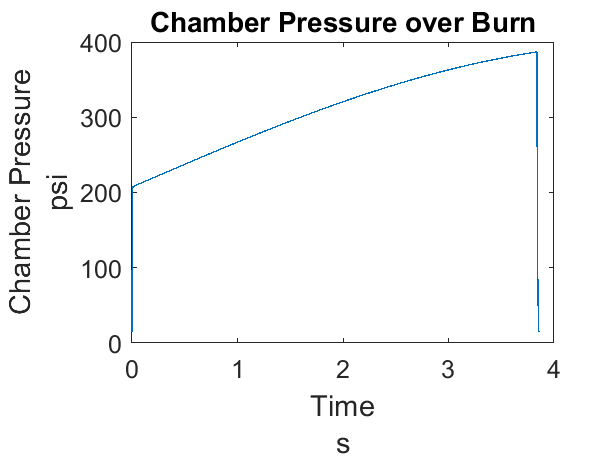

figure()
plot(t(1:i-1),PRec(1:i-1)./Pu)
title("Chamber Pressure over Burn")
xlabel({'Time',"s"}, 'FontSize', 11)
ylabel({'Chamber Pressure';Pl}, 'FontSize', 11)

fprintf("Average Pressure: %5.2f%s\n",P_avg/Pu,Pl);

Average Pressure: 308.98psi


fprintf("Max Pressure: %5.2f%s\n",P_max/Pu,Pl);

Max Pressure: 386.80psi


fprintf("Burn Time: %3.2fs\n\n",burn_time);

Burn Time: 3.84s




fprintf("Expansion Ratio: %4.3f\n",expansion_ratio);

Expansion Ratio: 3.749


fprintf("Exit Diameter: %5.5f%s\n",d_e/du,dl);

Exit Diameter: 0.82286in


fprintf("Exit Area: %5.5f%s\n\n",A_e/au,al);

Exit Area: 0.53180in^2



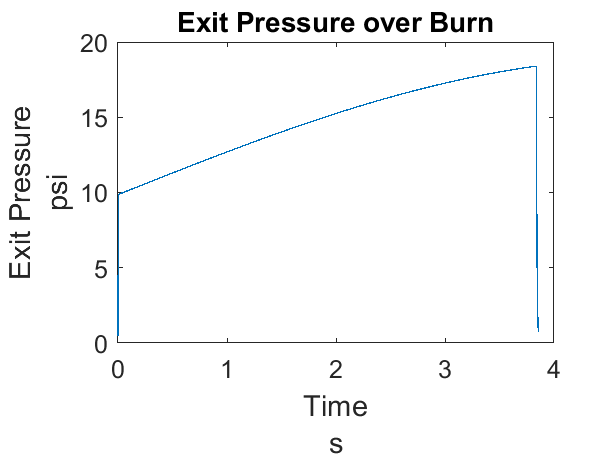


figure()
plot(t(1:i-1),P_eRec(1:i-1)./Pu)
title("Exit Pressure over Burn")
xlabel({'Time',"s"}, 'FontSize', 11)
ylabel({'Exit Pressure';Pl}, 'FontSize', 11)

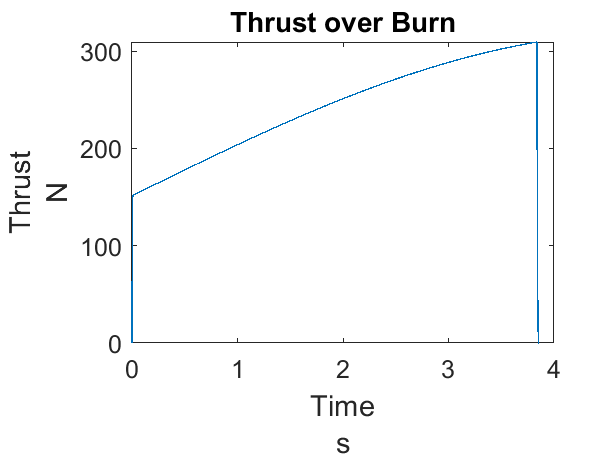


figure()
plot(t(1:i-1),FRec(1:i-1))
title("Thrust over Burn")
xlabel({'Time',"s"}, 'FontSize', 11)
ylabel({'Thrust';Fl}, 'FontSize', 11)


fprintf("Average Thrust: %5.2f%s\n",F_avg/Fu,Fl);

Average Thrust: 240.92N


fprintf("Max Thrust: %5.2f%s\n\n",F_max/Fu,Fl);

Max Thrust: 309.46N




fprintf("Total Impulse: %5.2f%ss\n",I_t/Iu,Il);

Total Impulse: 929.10Nss


fprintf("Specific Impulse: %5.2fs\n",Isp);

Specific Impulse: 183.29s


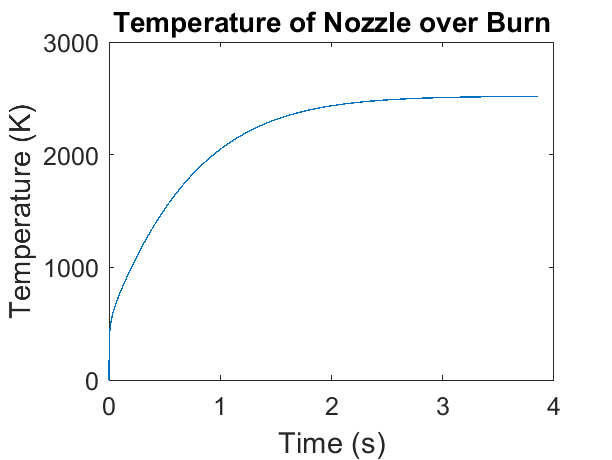

Max Temperature of Nozzle: 2517K




if(thermal)
    figure()
    plot(t(1:i-1),TRec(1:i-1))
    title("Temperature of Nozzle over Burn")
    xlabel('Time (s)', 'FontSize', 11)
    ylabel('Temperature (K)', 'FontSize', 11)

    fprintf("Max Temperature of Nozzle: %4.0fK\n\n",TRec(i-1));
end

## Functions

function xDot = chamber_pressure_dynamics(x,L,d_case,M_p,T_0,a,n,k_p,inhib,R,A_star,N_A,k_b,n_p,k_a,M_a)
    N_p = x(1); N_a = x(2); d_c = x(3); L_g = x(4);

    k = ((N_p*k_p+N_a*k_a)/(N_p+N_a));
    V = (L-L_g)*pi*(d_case/2)^2 + L_g*pi*(d_c/2)^2;
    P_0 = (N_a/V)*k_b*T_0+(N_p/V)*k_b*T_0;
    r = a*P_0^n;

    vDot = change_in_volume(L_g,d_c,r,d_case,inhib);
    m_pDot = (N_p/(N_p+N_a))*(mass_flow_rate_out(A_star,P_0,R,T_0,k));
    m_aDot = (N_a/(N_p+N_a))*(mass_flow_rate_out(A_star,P_0,R,T_0,k));
    
    if(d_c<d_case)
        N_pDot = n_p*vDot-(N_A/M_p)*m_pDot;
    else
        N_pDot = -(N_A/M_p)*m_pDot;
    end

    N_aDot = -(N_A/M_a)*m_aDot;
    d_cDot = 2*r;
    L_gDot = (inhib-2)*r;    

    xDot = [N_pDot;N_aDot;d_cDot;L_gDot];
end

function mDot = mass_flow_rate_out(A_star,P_0,R,T_0,k)
    mDot = ((A_star*P_0*k)/sqrt(R*T_0))*sqrt((2/(k+1))^((k+1)/(k-1)));
end

function vDot = change_in_volume(L_g,d_core,r,d_case, inhib)
    A_coreDot = pi*(((d_core/2)+r)^2-(d_core/2)^2);
    LDot = (2-inhib)*r;
    A_end = pi*((d_case/2)^2-((d_core/2)+r)^2);
 
    vDot = LDot*A_end + L_g*A_coreDot;
end

function [expan,d_e] = expansion_ratio_calcs(P_0,P_a,k,A_star)
    expan = ((((k+1)/2)^(1/(k-1)))*((P_a/P_0)^(1/k))*sqrt(((k+1)/(k-1))*(1-(P_a/P_0)^((k-1)/k))))^-1;

    A_e = expan*A_star;
    d_e = 2*sqrt(A_e/pi);
end

function P_e = exit_pressure_solver(A_star,A_e,k,P_0,P_e_p,accuracy)
    P_e = ((A_star/A_e)^k)*(((k+1)/2)^(k/(1-k)))*(((k-1)/(k+1))^(k/2))*...
        P_0*(1-((P_e_p/P_0)^((k-1)/k)))^(-k/2);

    if(abs(1-(P_e/P_e_p))>accuracy)
        P_e = exit_pressure_solver(A_star,A_e,k,P_0,P_e,accuracy);
    end
end

function F = thrust(mDot,P_e,P_a,A_e,k,R,T_0,P_0,beta,c_s,correction)
    [~, R] = two_phase_flow(R,k,beta,c_s);
    v_e = sqrt(((2*k)/(k-1))*R*T_0*((1-(P_e/P_0)^((k-1)/k))));
    v_e = correction*v_e;
    F = mDot*v_e + A_e*(P_e-P_a);
    if(F<0)
        F = 0;
    end
end

function [k,R] = two_phase_flow(R,k,beta,c_s)
    c_p = (k*R)/(k-1);
    c_v = c_p/k;
    
    k = (((1-beta)*c_p+beta*c_s)/((1-beta)*c_v+beta*c_s));
    R = (1-beta)*R;
end

function TDot = temperature_dynamics(TCurr,R,k,K_n,T0,P0,M_p,k_b,N_A,d,C_n,rho_n,t_n)
    Cp = R/(k-1);
    Pr = (2/5)*k;
    mu = Pr*(K_n/Cp);

    T = T0*(1+((k-1)/2))^-1;
    v = (k*R*T)^(1/2);
    rho0 = (P0*M_p)/(k_b*T0*N_A);
    rho = rho0*(1+((k-1)/2))^((k-1)/2);
    Re = (rho*v*d)/mu;

    St = 0.023*Re^(-1/5)*Pr^(-0.067);
    h = St*rho*v*Cp;
    QDot = h*(T-TCurr);
    TDot = QDot/(C_n*rho_n*t_n);
end